# Complex Fourier Series

**Learning Goals**

- Recall Euler's formula.

- Compare complex and real Fourier series.

- Visualize complex Fourier series.

- Construct real functions from complex Fourier series.

In this module, you will learn the definition of the complex Fourier series and visualize it in the complex plane. There are four essential reasons to learn about complex Fourier series:

- Complex frequency domain representations are more common in signal processing.

- The complex Fourier series bridges the gap between real Fourier series and the Fourier transform.

- The complex form is notationally more compact than real Fourier series.

- Integrals of exponentials are easier to compute than integrals of sines and cosines.

## Euler's Formula

Possibly the most surprising formula in mathematics, Euler's formula relates exponentials to trigonometric functions using complex numbers:


$$e^{i \theta} = \cos \theta + i \sin \theta$$


Pictured in the complex plane, Euler's formula traces out a circle. 

   **Task. **Slowly drag the slider below from 0 to 360 to trace out a circle using Euler's formula.

thetad = 133; % In degrees
complexCircle(thetad); % Helper function that generates the plot

By making the input $\theta$ a linear function of time, Euler's formula will trace out a circle with a speed of the angular frequency $\omega$:


$$y(t) = e^{ i \omega t}$$


The angular frequency has units of rad/s. Plotting each component separately with respect to time will produce two plots: the real component will trace out a cosine curve and the imaginary component will trace out a sine curve.

    **Task**. Set the frequency of $y(t)$ in the slider below or run the section to create an animated plot of $e^{ i \omega  t}$ in the complex plane along with the time series.

freq = 1; % frequency in Hz
omega = freq*2*pi; % angular frequency in rad/s
traceSineCosine(omega); % Helper function that traces the curve

## Complex Fourier Series

By changing the frequency in the function $e^{  i \omega t}$, you can create sine and cosine functions just like those in a standard Fourier series. However, the sines and cosines will be contained in real and complex parts of the function:


$$e^{ i \omega t} = \cos ( \omega t ) + i \sin (\omega t)$$


Combine many different frequencies together, and you can accurately capture a periodic signal.

### Definition

The complex Fourier series is defined as:


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


In this equation, $f$ is periodic with respect to the domain $[-L,L]$. The fundamental angular frequency $\omega_0$ is related to $L$ through $\omega_0 = \pi/L$. The coefficients of the complex Fourier series can be evaluated using the integral


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


The coefficents may be real or complex. Notice that if the function $y(t)$ is real, the coefficients $c_n$ are complex.

 **Exercise.** In this exercise, you will compare the complex Fourier series to the standard Fourier series.

**Task 1.** Expand the exponential in the complex Fourier series $f(t)$ defined above using Euler's formula.

**Task 2. **Compare the the expanded complex series to the real sine-cosine series:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


- What parts are the same?

- What parts are different?

### Complex Fourier Series Modes

Each mode of the complex Fourier series is more difficult to understand than a mode of the real series, because they contain both a real and imaginary part. Consider the $n^{th}$ mode of the series:


$$f_n(t) = c_n e^{\frac{i n \pi }{L} t}  = c_n \cos\left( \frac{ n \pi } {L}  t \right) + i c_n \sin \left( \frac{ n \pi } {L}  t \right)$$


Notice that if you set a real mode coefficient $c_n$, you get both a real cosine and imaginary sine curve simultaneously. To understand what this means, it's helpful to visualize a few modes.

    **Activity**. Visualize modes in the complex Fourier series app.

**Task 1. **Run the complex Fourier series app.

[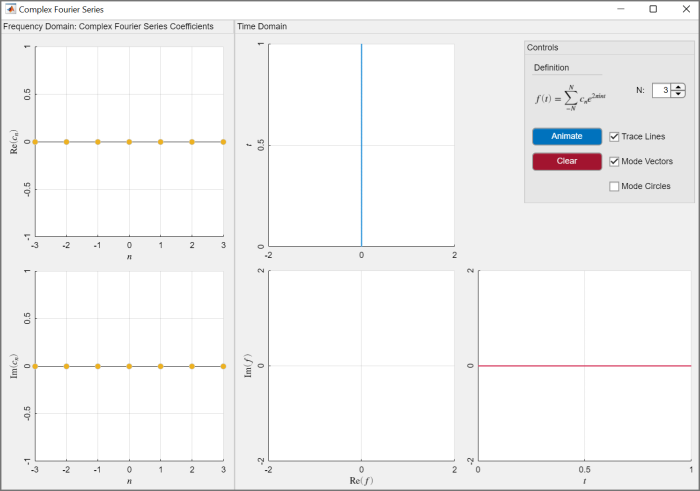](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Task 2. **The frequency domain is shown in the panel on the left side. Adjust the coefficient of the first mode ($n=1$) so that $c_1 = 1$. Leave all other $c_n = 0$.

- You can adjust the modes by clicking and dragging the coefficient stem plot. 

- You only need to adjust the first plot, which contains the real parts of the coefficients.

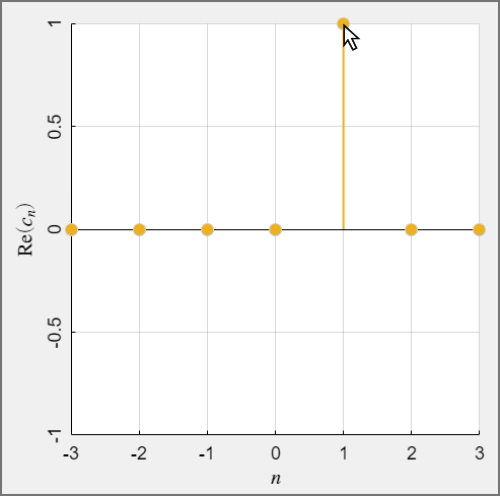

**Task 3. **Review the result in each plot. Review the axes labels carefully and the descriptions below to identify what is shown in each plot.

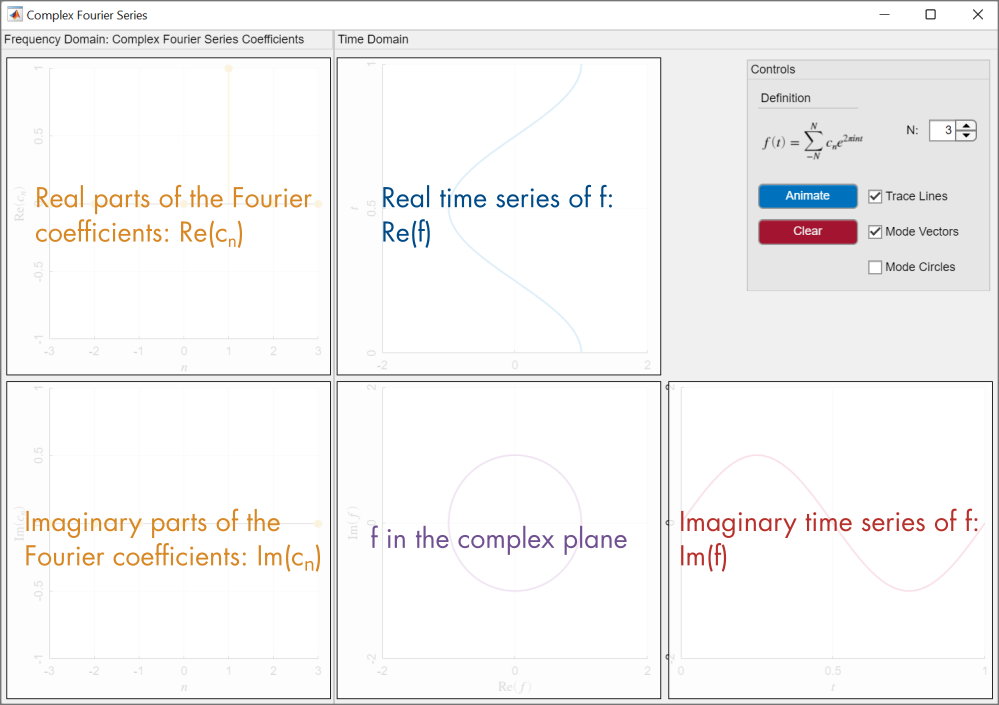

*Plots in the Complex Fourier Series app. Notice that in the real time series, the axes have been flipped so that the real component matches up with the real axis of the complex plane.*

**Task 4. **Press the **Animate **button to animate the mode over time. Notice that the mode contains both a real and imaginary component.

**Task 5. **Press the clear button to reset the coefficients.

**Task 6.** Adjust the coefficient of the first mode so that $c_1 = i$ (all other $c_n = 0$) and animate the plot.

-  Use the second plot ($\text{Im}(c_n)$) to adjust the imaginary part of the mode coefficient.

- The complex plot is unchanged when comparing $c_1 = 1$ vs. $c_1 = i$ (it still shows a unit circle). However, the time series have changed. What has changed?

**Task 7.** Clear the app. Then, create a mode with a complex coefficient: $c_1 = 1+i$. 

- How does the complex plot change? 

- How do the time series change?

**Task 8. **Repeat tasks 2-6, but use a higher frequency mode: n = 3. Continue to look at only one mode at a time.

- How does the complex plot change compared to the case where $n = 1$?

- How do the time series change compared to the case where $n = 1$?

In **Tasks 2-4**, you set $c_1 = 1$ (while all other $c_n = 0$). This means that Fourier series consisted of only one mode:

$f(t) = 1 e^{2 \pi i  t}  =  \cos\left(2  \pi  t \right) + i \sin \left( 2 \pi  t \right)$.

Notice that the real component of $f$ is a pure 1 Hz cosine wave (observed in the real time series), and the imaginary component is a pure 1 Hz sine wave (observed in the imaginary time series).

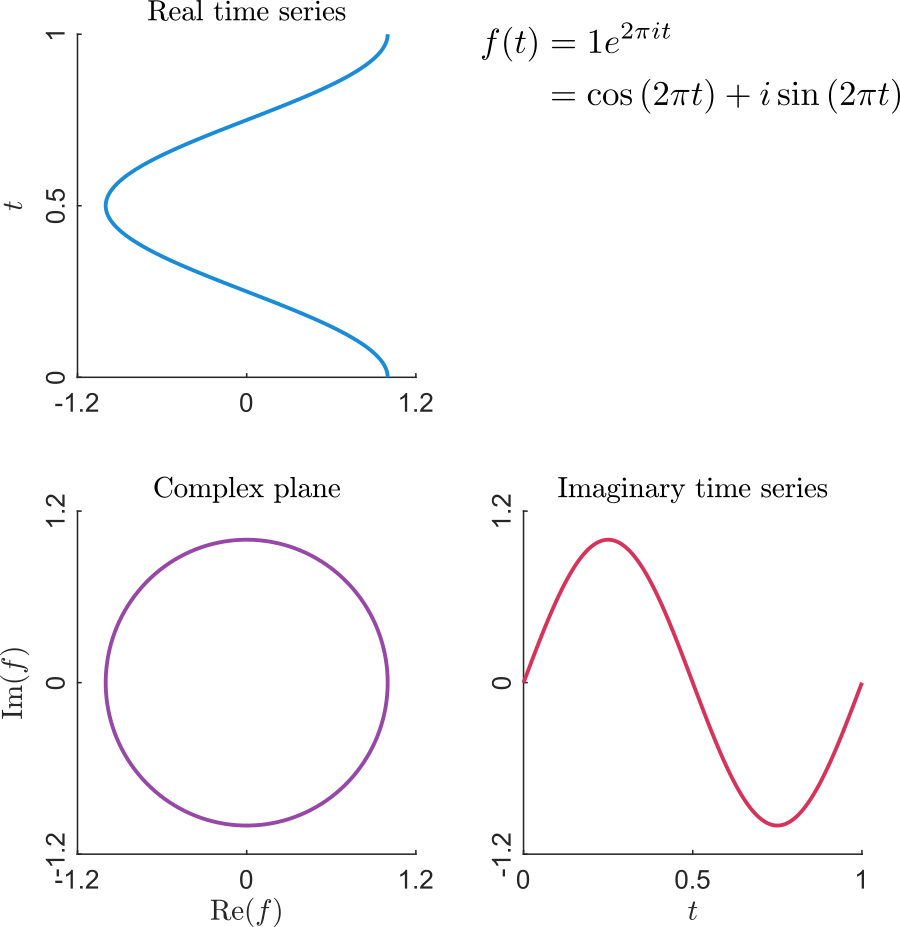

*Time domain plots of *$f$* with a single mode, *$c_1 = 1$.

 **Exercise.** By hand, write out the Fourier series with $c_1 = i$ and all other $c_n = 0$.

- What are the real and imaginary components of the Fourier series, $f$?

- How are these components reflected in the time series plots?

## Representing Real Functions with Complex Series

In the previous activity, you probably noticed that every mode comes with both a real and an imaginary component. Indeed, no matter what complex coefficient $c_n$ is selected (except 0), the mode will always contain a combination of real and imaginary parts.

So, how do you create a real-valued function from these modes? For example, what coefficients will create a pure 1 Hz sine wave:


$$y(t) = \sin( 2 \pi t)$$


The answer to combine positive and negative frequencies "just right" so that the imaginary parts cancel out.

### Real Modes from Complex

    **Activity**. In this activity, you will create real modes by combining complex modes.

**Task 1. **Run the complex Fourier series app.

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Task 2. **Set the Fourier coefficient $c_1 = 0.5$. 

**Task 3. **By adjusting the Fourier coefficient with the same but negative frequency ($c_{-1}$), you can produce a real signal. Adjust the real and/or complex part of $c_{-1}$ to produce a real signal.

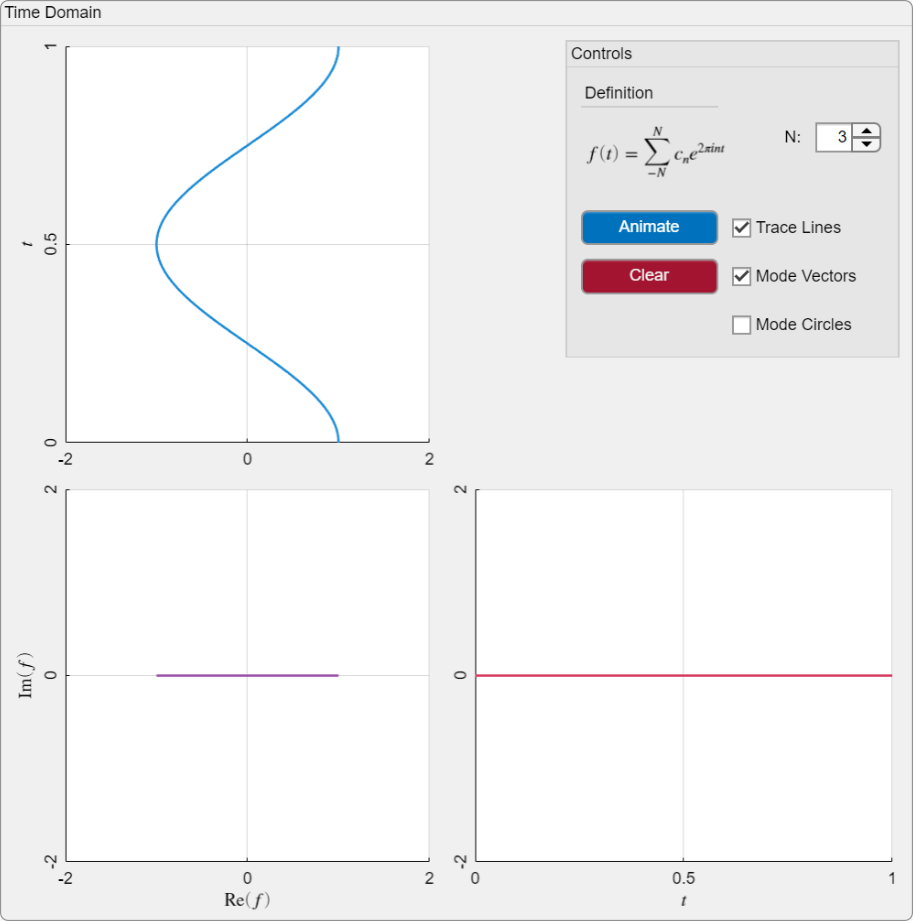

*If correct, you should find that you have created a real cosine curve. The imaginary component should be zero.*

**Task 4. **By hand, write out the Fourier series with the two coefficients that you used in **Tasks 2 **and** 3**. Use the definition given by the app:


$$f(t) = \sum_{-N}^N c_n e^{ 2 \pi i n t}$$


Then, simplify the result by expanding the complex exponentials using Euler's formula . If correct, you should find


$$f(t) = \cos(2 \pi t)$$


**Task 5. **Animate the plot. Notice that both complex modes exist, but are combined "just so" to cancel the imaginary part.

- Visualize the circular path of each complex mode by selecting the "Mode Circles" checkbox and rerunning the animation.

- Notice that the two complex circles have the same frequency and magnitude, but are traversed in opposite directions (the result of the negative frequency).

**Task 6. **In **Tasks 2-4**, you found the coefficients that would produce a real 1 Hz cosine wave from the complex Fourier transform. Consider the expansion that you did in **Task 4 **with only $c_1$ and $c_{-1}$:


$$f(t) = c_{-1} e^{ - 2 \pi i t} + c_{1} e^{ 2 \pi i t}$$


Can you identify complex coefficients $c_1$ and $c_{-1}$ that will produce a real 1 Hz sine wave? Type your answer below.

  **Pro-tip.** To write a complex number, you can use standard mathematical notation. For example, $w = 3+2i$ can be written in MATLAB as 

% Replace NaN with your answers
cm1 = 0.5i; % c_{-1}
c1 = -0.5i; % c_1

**Task 7. **Check your result by setting the coefficients inside the app to the values you identified in** Task 6**. Then, animate the plot. 

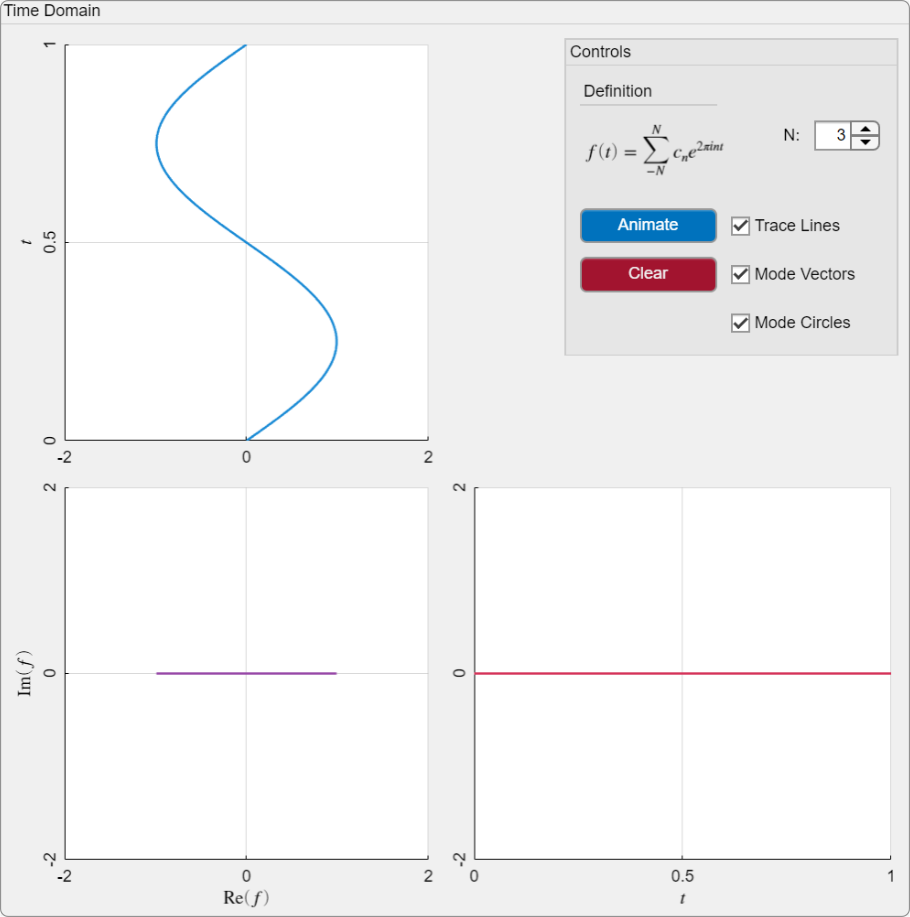

**Relationship between Real and Complex Series**

In general, to produce a real mode, the negative frequency coefficient $c_{-n}$ must be the complex conjugate of the corresponding positive frequency mode $c_n$: $c_{-n} = {c_n}^*$. Recall that the complex conjugate of $a + bi$ is $a - bi$. You can show that this is exactly what is needed to "cancel out" the imaginary component of the series. This fact leads to the relationship between real and complex Fourier series. Consider the real sine-cosine Fourier series


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


The corresponding complex Fourier series is

$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$    with    $c_n = \frac{1}{2} \left\{
 \begin{array}{rl} 
a_0; & n = 0 \\ 
a_n - i b_n; & n > 0 \\ 
a_{-n} + i b_{-n}; & n < 0 \\ 
 \end{array}
 \right.$

 **Exercise.** Write the complex Fourier series in terms of $a_n$ and $b_n$ and apply Euler's formula. Verify that the result is equivalent to the real Fourier series.

### Mode Combinations

In the last activity, you combined complex modes to create real sines and cosines. With those real building blocks, you can combine many frequencies to reproduce a desired periodic function, just like you would with real Fourier series.

    **Activity**. In this activity, you will combine several modes to create a real function.

**Task 1. **Run the complex Fourier series app.

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Task 2. **Open

function checkEx1Task1(a1,a2,b1,b2)
    isEqualCheck([a1,a2,b1,b2],[3,2,0,1])
end

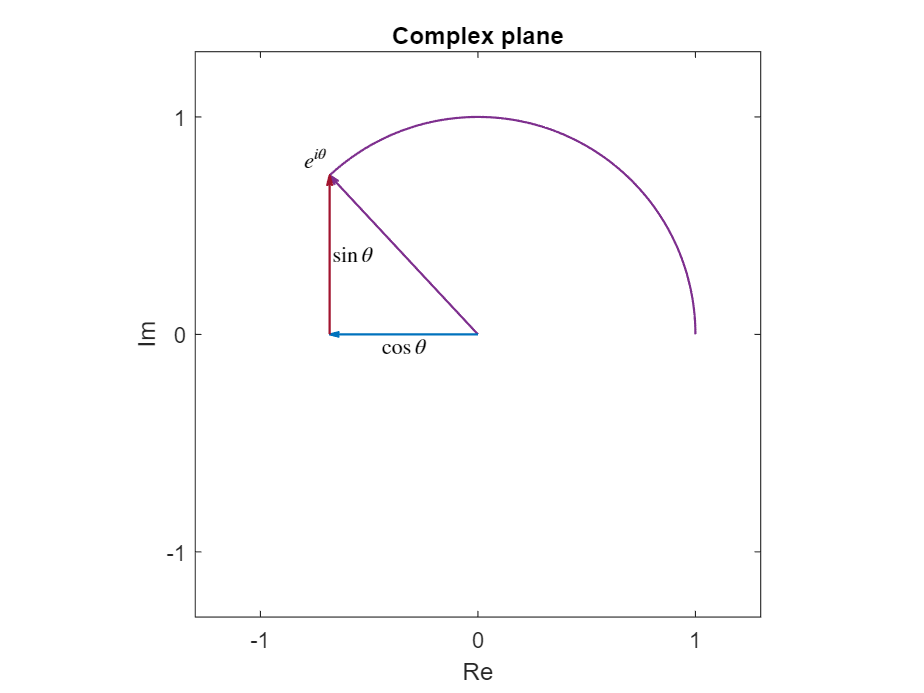

function checkEx1Task2(A1,A2,phi1,phi2)
    isEqualCheck([A1,A2,phi1,phi2],[3,sqrt(5),0,atan2(1,2)])
end

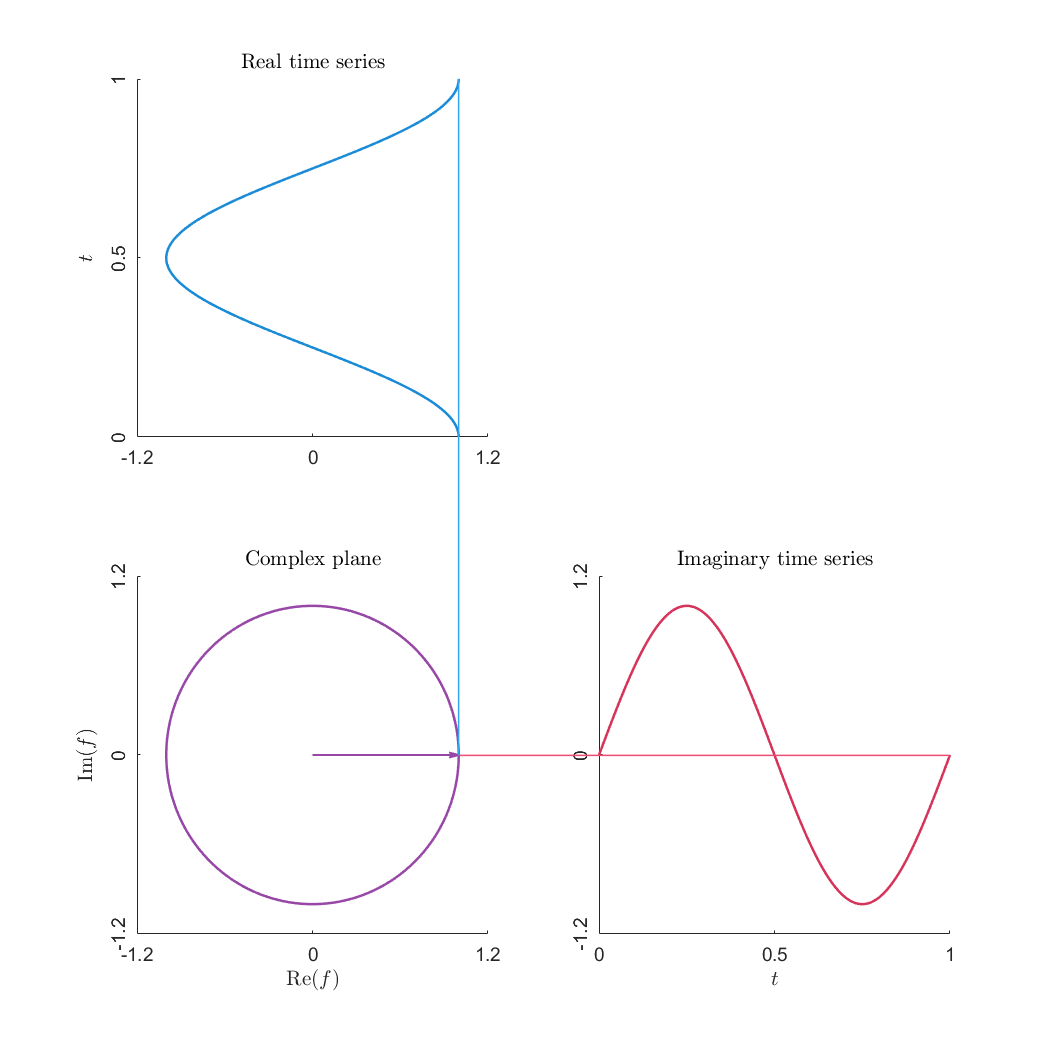


function isEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are equal and displays feedback
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end

end

function complexCircle(theta)
    % This function traces out a circle in the complex plane
    % With labels for Euler's formula
    
    f = exp(1i*theta * pi/180);
    thetaVec = 0:theta;
    fc = exp(1i*thetaVec*pi/180);
    
    colors = lines(7);
    
    figure
    quiver(0,0,real(f),imag(f),"off","LineWidth",1,"color",colors(4,:))
    hold on
    plot(real(fc),imag(fc),"LineWidth",1,"color",colors(4,:))
    quiver(0,0,real(f),0,"off","LineWidth",1,"color",colors(1,:))
    quiver(real(f),0,0,imag(f),"off","LineWidth",1,"color",colors(7,:))
    text(real(f)/2,0,"$\cos \theta$","Interpreter","latex",...
        "VerticalAlignment","top","HorizontalAlignment","center")
    text(real(f),imag(f)/2,"$\sin \theta$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","left")
    text(real(f)*1.1,imag(f)*1.1,"$e^{i \theta}$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","center")
    hold off
    
    axis equal
    axis(1.3*[-1 1 -1 1])
    xlabel("Re")
    ylabel("Im")
    title("Complex plane")
    xticks([-1,0,1])
    yticks([-1,0,1])
end


function pFig = figPos(ax,p)
    % This function computes the position of points
    % in the figure

    axUnits = ax.Units;
    ax.Units = 'normalized';
    pos = ax.InnerPosition;

    % Shifted so that the origin is at the lower-left corner
    x = p(1)-ax.XLim(1);
    y = p(2)-ax.YLim(1);
    
    % Compute the position of the point in the figure
    xFig = x*(pos(3))/(ax.XLim(2) - ax.XLim(1)) + pos(1);
    yFig = y*(pos(4))/(ax.YLim(2) - ax.YLim(1)) + pos(2);
    
    pFig = [xFig,yFig];
    ax.Units = axUnits;
end

function traceSineCosine(omega)

    freq = omega/(2*pi);

    % This defines the function
    Nt = 150;
    tvec = linspace(0,1,Nt);
    fvec = exp(freq*2*pi*1i*tvec);
    
    % Appearance settings
    timeColors = [     0    0.4470    0.7410;
        0.7350    0.1000    0.2500;
        0.4940    0.1840    0.5560]+0.1;
    
    imLims = 1.2*[-1,1]; % Im limits on complex plane
    reLims = 1.2*[-1,1]; % Re limits on complex plane       
    
    lwSeries = 1.25;
    lw = 0.75;

    % Set up the axes
    figure("position",[1,1,700,700])
    ax1 = subplot(2,2,3);
    ax2 = subplot(2,2,1);
    ax3 = subplot(2,2,4);
    
    % Plots
    reLine = plot(ax2,tvec*0,tvec,...
        "linewidth",lwSeries,"color",timeColors(1,:));
    imLine = plot(ax3,tvec,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(2,:));     
    hold(ax1,"on")
    cmplxLine = plot(ax1,tvec*0,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(3,:));
    arrow = quiver(ax1,0,0,0,0,"off","LineWidth",1,"color",timeColors(3,:));
    hold(ax1,"off")

    % Change graph appearance: complex plane
    set(ax1,"XLimMode","manual","YLimMode","manual")
    box(ax1,"off")
    xlim(ax1,reLims)
    ylim(ax1,imLims)
    xticks(ax1,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax1,[imLims(1), mean(imLims),imLims(2)])
    xlabel(ax1,"Re$(f)$","interpreter","latex")
    ylabel(ax1,"Im$(f)$","interpreter","latex")
    title(ax1,"Complex plane","Interpreter","latex")
    ytickangle(ax1,90)
    
    % Graph appearance: real 
    box(ax2,"off")
    set(ax2,"XLimMode","manual","YLimMode","manual")
    xlim(ax2,reLims)
    ylim(ax2,[tvec(1),tvec(end)])
    xticks(ax2,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax2,[tvec(1), mean(tvec),tvec(end)])
    ylabel(ax2,"$t$","interpreter","latex")
    title(ax2,"Real time series","Interpreter","latex")
    ytickangle(ax2,90)
    
    % Graph appearance: imaginary
    box(ax3,"off")
    set(ax3,"XLimMode","manual","YLimMode","manual")
    ylim(ax3,imLims)
    xlim(ax3,[tvec(1),tvec(end)])
    yticks(ax3,[imLims(1), mean(imLims),imLims(2)])
    xticks(ax3,[tvec(1), mean(tvec),tvec(end)])
    xlabel(ax3,"$t$","interpreter","latex")
    title(ax3,"Imaginary time series","Interpreter","latex")
    ytickangle(ax3,90);
    
    crossLine1 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(1,:)+0.1);
    crossLine2 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(2,:)+0.1);
    
    for k = 1:numel(tvec)
        t = tvec(k);
        f = fvec(k);
        
        % This code creates the connecting lines
        pComplex = [real(f),imag(f)];
        pReal = [real(f),t];
        pImag = [t,imag(f)];
        
        pCFig = figPos(ax1,pComplex);
        pRFig = figPos(ax2,pReal);
        pIFig = figPos(ax3,pImag);
        
        % Update the curves
        cmplxLine.XData = real(fvec(1:k));
        cmplxLine.YData = imag(fvec(1:k));
        
        reLine.XData = real(fvec(1:k));
        reLine.YData = tvec(1:k);
        
        imLine.XData = tvec(1:k);
        imLine.YData = imag(fvec(1:k));
        
        arrow.UData = real(fvec(k));
        arrow.VData = imag(fvec(k));
        
        % Create annotation between the axes
        p1 = [real(f),imag(f)];
        p2 = [real(f),t];
        p3 = [t,imag(f)];
        
        p1Fig = figPos(ax1,p1);
        p2Fig = figPos(ax2,p2);
        p3Fig = figPos(ax3,p3);
        
        crossLine1.X = [p1Fig(1),p2Fig(1)];
        crossLine1.Y = [p1Fig(2),p2Fig(2)];
        
        crossLine2.X = [p1Fig(1),p3Fig(1)];
        crossLine2.Y = [p1Fig(2),p3Fig(2)];

    
        drawnow
    end
end